# 2-Dimensional $H_\infty$ Controller for Canted-Rotors Octocopter (4 States) - WIP

clearvars; clc; % clean-up

## System equations

The equations of motion are defined as:

$\ddot{x} =  \frac{1}{m_\mathrm{UAV}} \big( \, (T + F_{zb}) \sin\theta + (T_{xb} + F_{xb})\cos\theta \, \big)$,

$\ddot{z} = \frac{1}{m_\mathrm{UAV}} \big( \, (T + F_{zb}) \cos\theta + (T_{xb} + F_{xb})\sin\theta \, \big) + g$,


$$\ddot{\theta} = \frac{1}{J_\mathrm{UAV}} ( M + M_\mathrm{aero} )$$


where $T$ and $T_{xb}$ represent the vertical and horizontal forces produced by the UAV's rotors. Likewise, $M$ represents the pitching moment applied by differencial rotor commands. These forces and moment are defined as

$T = - C_T \cos\zeta \sum_{i=1}^8 {\omega_i}^2$,

$T_{xb} = 2 C_T \sin\zeta ( {\omega_3}^2 - {\omega_2}^2 )$,


$$M = 2 C_T D_\mathrm{UAV} \cos\zeta \left( {\omega_1}^2 \sin 22.5^\circ + {\omega_2}^2 \cos 22.5^\circ - {\omega_3}^2 \cos 22.5^\circ -{\omega_4}^2 \sin 22.5^\circ \right)$$


where $C_T$ is the rotors' coeffcient of lift, $\zeta$ is the cant angle of the motors, $D_\mathrm{UAV}$ is the distance between opposite pairs of rotors, and $\omega_i$ is the rotational speed of rotor $i$. The rotor numbers are shown in Figure 1b.

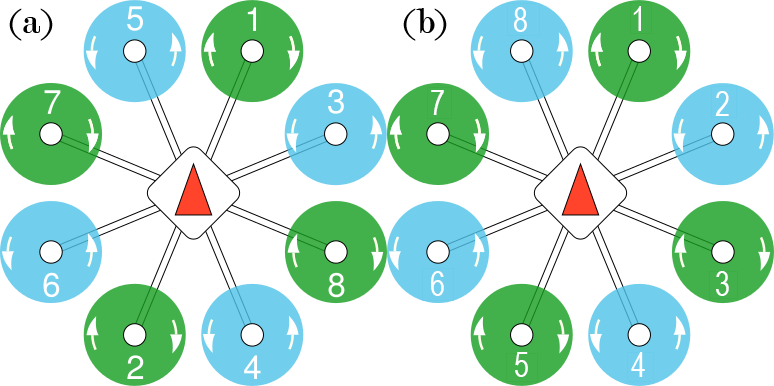

**Figure 1:** Rotor numbers (a) as seen by PX4 firmware, (b) used for modelling the system. **[Rotor directions might need to be inverted]**

The other forces acting on the UAV, $F_{zb}$ and $F_{xb}$, are vertical and horizontal aerodynamic forces. Likewise, $M_\mathrm{aero}$ is an aerodynamic pitching moment. These forces and moment are defined as

$F_{xb} = \frac{1}{2} \rho A_\mathrm{UAV} C_{xb,1} U^2 +  \frac{1}{2} \rho A_\mathrm{prop} D_\mathrm{prop} \frac{n}{4} C_{xb,2} U \bar{\omega}$,

$F_{zb} = \frac{1}{2} \rho A_\mathrm{UAV} C_{zb,1} U^2 +  \frac{1}{2} \rho A_\mathrm{prop} D_\mathrm{prop} \frac{n}{4} C_{zb,2} U \bar{\omega}$,


$$M_\mathrm{aero} = \frac{1}{2} \rho A_\mathrm{UAV} D_\mathrm{UAV} C_{M,1} U^2 +  \frac{1}{2} \rho A_\mathrm{prop} {D_\mathrm{prop}}^2 \frac{n}{4} C_{M,2} U \bar{\omega}$$


where $U$ is the effective wind speed acting on the UAV and $\bar{\omega}$ is the mean rotor speed. $n$ is the number of rotors, $\rho$ is the air density, $A_\mathrm{UAV}$ and $A_\mathrm{prop}$ are representative areas for the UAV and rotor respectively and $D_\mathrm{prop}$ is the diameter of a propeller. $C_{xb,1}$, $C_{xb,2}$, $C_{zb,1}$, $C_{zb,2}$, $C_{M,1}$, and $C_{M,2}$ are dimensionless aerodynamic coefficients defined as

$C_{xb,1} = -0.241\cos\alpha + 0.036\cos(3\alpha) + 0.016\cos(7\alpha)$,

$C_{xb,2} = -0.053\cos\alpha - 0.008\cos(3\alpha)$,

$C_{zb,1} = -0.724\sin\alpha + 0.080$,

$C_{zb,2} = -0.222\sin\alpha + 0.065$,

$C_{M,1} =  0.009\cos\alpha + 0.003\cos(3\alpha) - 0.014\sin(2\alpha)$,

$C_{M,2} =  A_1\cos\alpha + A_2\sin(2\alpha)$,

where $\alpha$ is the angle of attack of the wind. $A_1$ and $A_2$ are defined as

$A_1  =  0.116 ( 1 - e^{-0.126\lambda} )$,


$$A_2  = -0.041 ( 1 - e^{-0.308\lambda} )$$


where


$$\lambda = \frac{\bar{\omega} D_\mathrm{prop} }{ 2 U }$$


is the mean rotor tip-speed ratio.

## $H_\infty$ Controller Definition

Following the conventions highlighted in [1], the standard $H_\infty$ controller is shown in Figure 2.

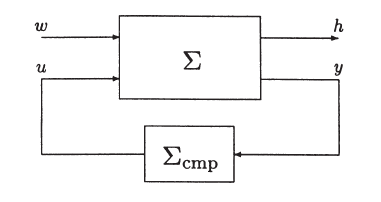

**Figure 2:** The standard $\mathcal{H}_\infty$-optimization problem. Retrieved from [1].

The plant and controller (compensator), $\Sigma$ and $\Sigma_\mathrm{cmp}$ respectively, are defined as


$$\Sigma :
\begin{cases}
\dot{\mathbf{x}} = \mathbf{A} \mathbf{x} + \mathbf{B}_1 \mathbf{\omega} + \mathbf{B}_2 \mathbf{u} \\
\mathbf{z} = \mathbf{C}_1 \mathbf{x} + \mathbf{D}_{12} \mathbf{u}\\
\mathbf{y} = \mathbf{C}_2 \mathbf{x} + \mathbf{D}_{21} \mathbf{\omega}
\end{cases} \enspace,$$



$$\Sigma_\mathrm{cmp} :
\begin{cases}
\dot{\mathbf{v}} = \mathbf{A}_\mathrm{cmp} \mathbf{v} + \mathbf{B}_\mathrm{cmp} \mathbf{y} \\
\mathbf{u} = \mathbf{C}_\mathrm{cmp} \mathbf{v} + \mathbf{D}_\mathrm{cmp} \mathbf{y}
\end{cases} \enspace.$$


where $\mathbf{x}$ is the state vector, $\mathbf{z}$ is the control output vector, $\mathbf{\omega}$ is noise input vector, and $\mathbf{u}$ is the input vector.

## Variable Choices for Controller

We first create the simplest controller possible. For the sake of this controller, we completely disregard the dynamics of the controller and motors. We assume we can directly control the mean rotor force $T_R$, the horizontal thrust, $T_{R,xy}$, and a pitching moment $M_R$ 

$\mathbf{u} = \left[\matrix{ \theta & T & T_{xy}} \right]^\top$ .

Next, we choose the state variables. As we disregarded all extraneous dynamics, we are left with four states:

$\mathbf{x} = \left[\matrix{ x & \dot{x} & z & \dot{z}}\right]^\top$.

The wind speed, $U$, is included in the disturbance vector. In addition, in order to be able to develop a standard $H_\infty$ controller, $\mathbf{D}_{21}$ must be full row rank. As a consequence, a measurement error $d_i$ is added for each state.

$\mathbf{\omega} = \left[\matrix{ U & d_x & d_z & d_\dot{x} & d_\dot{z}} \right]^\top$.

We include the position and velocity states in the regulated output vector since those are the states we want to regulate. In addition, in order to try to minimise the magnitude of the inputs, we include them in the regulated output. This also has the effect of meeting the requirement of $\mathbf{D}_{12}$ being full column rank.

$\mathbf{z} = \left[\matrix{ \mathbf{x} & \mathbf{u} }\right]^\top = \left[\matrix{ x & \dot{x} & z & \dot{z} & \theta & T & T_{xy}  }\right]^\top$.

From this, we can already define the $\mathbf{C}_1$ and $\mathbf{D}_{12}$ matrices as

$\mathbf{C}_1 =  \left[\matrix{ 1 & 0 & 0 & 0 \cr 0 & 1 & 0 & 0 \cr 0 & 0 & 1 & 0 \cr 0 & 0 & 0 & 1 \cr \mathbf{0} } \right], \mathbf{D}_{12} = \left[\matrix{ \mathbf{0} \cr \mathbf{I} } \right]$.

We assume that all states are measured.

$\mathbf{C}_2 = \mathbf{I}, \mathbf{D}_{21} = \left[\matrix{ \mathbf{0} & \mathbf{I} } \right]$.

## Linearisation of Simulink Model

We then use MATLAB to linearise our simplified simulink model to obtain the $\mathbf{A}$, $\mathbf{B}_1$, and $\mathbf{B}_2$ matrices.

LineariseOctocopter2D % Load parameters
mdl = 'Octocopter2D_04States';
opspec = operspec(mdl);

We first trim the model. We do so around an arbitatry wind speed of 5 m/s.

% Configure the states for trimming
% Theta
% opspec.States(1).SteadyState = 1;
% opspec.States(1).Min = -deg2rad(45);
% opspec.States(1).Max = deg2rad(45);
% opspec.States(1).x   = 0;

% All the states should be zero
for i = 1:length(opspec.States)
    opspec.States(i).SteadyState = 1;
    opspec.States(i).Known = 1;
    opspec.States(i).x = 0;
end

% Inputs: there should be no horizontal thrust, the tilt angle should be within +-45deg and the wind speed should be 5 m/s
opspec.Inputs(1).Min = -deg2rad(45);
opspec.Inputs(1).Max = deg2rad(45);
opspec.Inputs(3).Known = 1;
opspec.Inputs(3).u = 0;
opspec.Inputs(4).Known = 1;
opspec.Inputs(4).u = 5;

% Set optimizer type - the default (gradient descent) does not work well in this case
opt = findopOptions('OptimizerType','simplex');
op = findop(mdl, opspec, opt)


 Operating point search report:
---------------------------------

 Operating point search report for the Model Octocopter2D_04States.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
(1.) x
      x:             0      dx:             0 (0)
(2.) z
      x:             0      dx:             0 (0)
(3.) xDot
      x:             0      dx:         -4.23 (0)
(4.) zDot
      x:             0      dx:          4.73 (0)

Inputs: 
----------
(1.) O


% Create vectors for use in simulation
for i = 1:length(op.States)
    x0(i) = op.States(i).x;
end

for i = 1:(length(op.Inputs)-1)
    u0(i) = op.Inputs(i).u;
end

We then use the operating point to linearise the system.

linsys = linearize(mdl,op)


linsys =
 
  A = 
               x        z     xDot     zDot
   x           0        0        1        0
   z           0        0        0        1
   xDot        0        0   -1.308  -0.5033
   zDot        0        0   -1.686   -1.137
 
  B = 
             Pitch     Thrust  HorThrust          U
   x             0          0          0          0
   z             0          0          0          0
   xDot     -5.435    -0.2161     0.5633     -1.308
   zDot     -4.855    -0.1931     0.3565     -1.686
 
  C = 
            x     z  xDot  zDot
   x        1     0     0     0
   z        0     1     0     0
   xDot     0     0     1     0
   zDot     0     0     0     1
 
  D = 
             Pitch     Thrust  HorThrust          U
   x             0          0          0          0
   z             0          0          0          0
   xDot          0          0          0          0
   zDot          0          0          0          0
 
Continuous-time state-space model.



We can take a look at some of the properties of the linearised system. For example,

oltf = tf(linsys)


oltf =
 
  From input "Pitch" to output...
            -5.435 s - 3.734
   x:  --------------------------
       s^3 + 2.444 s^2 + 0.6381 s
 
            -4.855 s + 2.811
   z:  --------------------------
       s^3 + 2.444 s^2 + 0.6381 s
 
             -5.435 s - 3.734
   xDot:  ----------------------
          s^2 + 2.444 s + 0.6381
 
             -4.855 s + 2.811
   zDot:  ----------------------
          s^2 + 2.444 s + 0.6381
 
  From input "Thrust" to output...
           -0.2161 s - 0.1485
   x:  --------------------------
       s^3 + 2.444 s^2 + 0.6381 s
 
           -0.1931 s + 0.1118
   z:  --------------------------
       s^3 + 2.444 s^2 + 0.6381 s
 
            -0.2161 s - 0.1485
   xDot:  ----------------------
          s^2 + 2.444 s + 0.6381
 
            -0.1931 s + 0.1118
   zDot:  ----------------------
          s^2 + 2.444 s + 0.6381
 
  From input "HorThrust" to output...
           0.5633 s + 0.4608
   x:  --------------------------
       s^3 + 2.444 s^2 + 0.6

## Conversion of Linear Model to Standard $H_\infty$ State-Space Form

Those matrices are then split to fit the standard $H_\infty$ form.

Collecting theses equations we obtain the system equation in a parallel matrix notation as


$$\mathbf{P}_\Sigma = \left[ \matrix{
\mathbf{A} & \mathbf{B}_1 & \mathbf{B}_2 \cr
\mathbf{C}_1 & \mathbf{0} & \mathbf{D}_{12} \cr
\mathbf{C}_2 & \mathbf{D}_{21} & \mathbf{0}
} \right]$$


% Check requirements for Hinf control
nmeas = 4;
ncon  = 3;

% Get matrices
A = linsys.A;
B2 = linsys.B(:,1:ncon);
B1 = [linsys.B(:,ncon+1:end),zeros(size(A,1))];
%B1 = [linsys.B(:,ncon+1:end)];

C1 = [linsys.C; zeros(size(B2,2),size(linsys.C,2))];
D12 = [zeros(size(linsys.C,1), size(B2,2)); eye(size(B2,2))];
%D12 = [zeros(size(linsys.C,1), size(B2,2)); eye(size(B2,2))];

C2 = eye(length(A));
D21 = [zeros(size(C2,1),1), eye(size(C2,1))];
%D21 = [zeros(size(C2,1),1)];

% The following checks are necessary for the method presented in ELECTENG704 but not necessarily
% hinfsyn - need further investigation
% (A,B1,C1) needs to be controllable and observable
unCtrlStates = length(A) - rank( ctrb(A,B1) )

unCtrlStates = 1

unObsvStates = length(A) - rank( obsv(A,C1) )

unObsvStates = 0


% (A,B2,C2) needs to stabilisable and detectability
G = ss(A,B2,C2,zeros(size(C2,1),size(B2,2)));
[GS,GNS] = stabsep(G); % Split into stable and unstable parts
unDtctStates = length(GNS.A) - rank(obsv(GNS))

unDtctStates = 0

unObsvStates = length(A) - rank( obsv(A,C2) ) % Temporary, observable implies detectable

unObsvStates = 0


% Pack the matrices
BPack = [ B1 B2 ];
CPack = [ C1; C2 ];
DPack = [ zeros(size(C1,1),size(B1,2)) D12; D21 zeros(size(C2,1),size(B2,2)) ];
Psig = pck( A, BPack, CPack, DPack );

We try two methods, first a state feedback controller

gSuccessful = 100; g = gSuccessful/2; ind = 0;
while ind < 20
    g
    suitable = true;
    
    try
        P = are(A, -(B1*B1')/g^2 + B2*B2', C1'*C1);
    catch
        suitable = false;
    end
%     Q = are(A', -C1'*C1/g^2 + C2'*C2, B1*B1');

%     eigObsvHinf = eig(A + Q*(C1'*C1/g^2 - C2'*C2));
    eigHinf = eig(A + ((B1*B1')/(g^2) - (B2*B2'))*P);

    % Check stability
    if max(real(eigHinf) > 0) % || max(real(eigObsvHinf) > 0) )
        suitable = false;
    end
    
%     Mgam = [ A, ((B1*B1')/(g^2) - (B2*B2')); -C1'*C1, -A' ];
%     [Vs,d] = eig(Mgam);
%     n = size(Mgam,1)/2;
%     Vs1 = Vs(1:n,:);
%     Vs2 = Vs(n+1:2*n,:);
%     P=real(Vs2/Vs1);

    % Check positive semi-definite
    [~,notPosDef] = chol(P);
    if notPosDef
        suitable = false;
    end
    
    suitable 
    % Check spectral radius
%     if (max(abs(eig(P))) > g^2)
%         suitable = false;
%     end
    
    if (suitable == false)
        gTemp = g;
        g = g + (gSuccessful(end) - g)/2;
    else
        gTemp = g;
        g = g - (gSuccessful(end) - g)/2;
        gSuccessful(end+1) = gTemp;
    end
    ind = ind + 1;
end

g = 50

suitable = logical
   1


g = 25

suitable = logical
   1


g = 12.5000

suitable = logical
   1


g = 6.2500

suitable = logical
   1


g = 3.1250

suitable = logical
   0


g = 4.6875

suitable = logical
   1


g = 3.9063

suitable = logical
   1


g = 3.5156

suitable = logical
   0


g = 3.7109

suitable = logical
   1


g = 3.6133

suitable = logical
   1


g = 3.5645

suitable = logical
   0


g = 3.5889

suitable = logical
   1


g = 3.5767

suitable = logical
   0


g = 3.5828

suitable = logical
   1


g = 3.5797

suitable = logical
   1


g = 3.5782

suitable = logical
   1


g = 3.5774

suitable = logical
   0


g = 3.5778

suitable = logical
   0


g = 3.5780

suitable = logical
   0


g = 3.5781

suitable = logical
   1



K = -B2'*P

K =    37.5640   47.9414  -60.4920   69.4303
    1.4952    1.9083   -2.4079    2.7636
  214.1850  282.9335 -364.8869  410.3705



% Display results
g = gSuccessful(end)

g = 3.5781

Then an output feedback controller.

gmin = 0.1; gmax = 55; tol = 1e-9;
[ K, CLS, gsyn ] = hinfsyn( Psig, nmeas, ncon, gmin, gmax, tol );


  [a b1;c2 d21] does not have full row rank at s=0 


Output argument "r12" (and maybe others) not assigned during call to "hinf_st".

Error in hinfsyn (line 170)
  [p,r12,r21,fail,gmin] = hinf_st(p,nmeas,ncon,gmin,gmax,quiet);

[ACmp,BCmp,CCmp,DCmp] = unpck(K)

## Response of Linear System

Figure 3 shows a Simulink model of the linearised controller. We set the all the initial conditions to 0 apart from the initial $x$ position to 1.

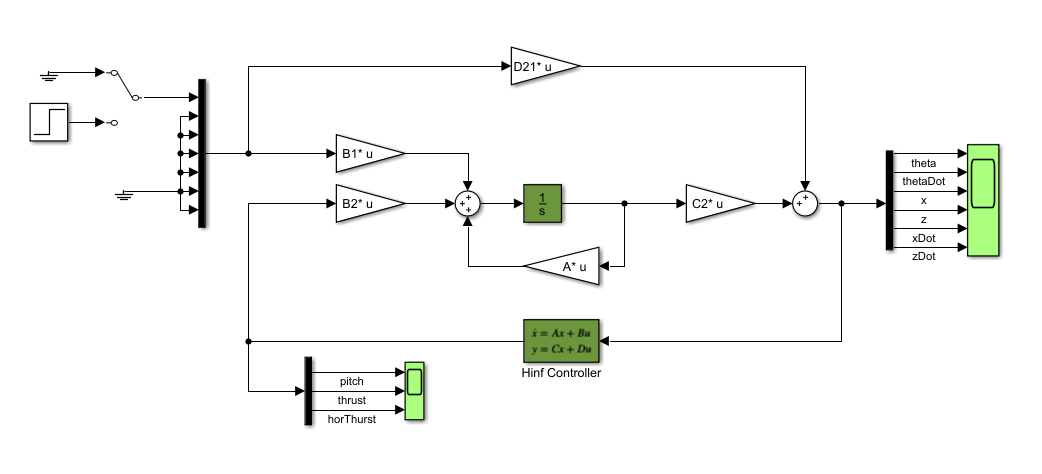

**Figure 3:** Simulink model of linearised system and $H_\infty$ controller

mdlLin = 'Octocopter2DLin';
xInit = zeros(length(A),1);
xInit(1) = 1;
output = sim( mdlLin, 'SimulationMode', 'normal');

figure
plot(output.tout, output.y(:,3),output.tout,output.y(:,4))
grid on; hold on;
xlabel('Time (s)','Interpreter','latex'); ylabel('Position (m)','Interpreter','latex')
legend({'$x$','$z$'},'Interpreter','latex')

figure
plot(output.tout, output.y(:,5),output.tout,output.y(:,6))
grid on; hold on;
xlabel('Time (s)','Interpreter','latex'); ylabel('Velocity (m/s)','Interpreter','latex')
legend({'$\dot{x}$','$\dot{z}$'},'Interpreter','latex')

figure
plot(output.tout, rad2deg(output.y(:,1) + x0(1)) )
grid on; hold on;
xlabel('Time (s)','Interpreter','latex'); ylabel('Pitch ($^\circ$)','Interpreter','latex')

figure
plot(output.tout, output.u(:,1),output.tout,output.u(:,2))
grid on; hold on;
xlabel('Time (s)','Interpreter','latex'); ylabel('Thrust (N)','Interpreter','latex')
legend({'$T_r$','$T_\mathrm{r,hor}$'},'Interpreter','latex')

## References

- Chen, B. M. $\mathcal{H}_\infty$ Control and Its Applications. *Springer, ***1998***, 235*